# Shallow shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

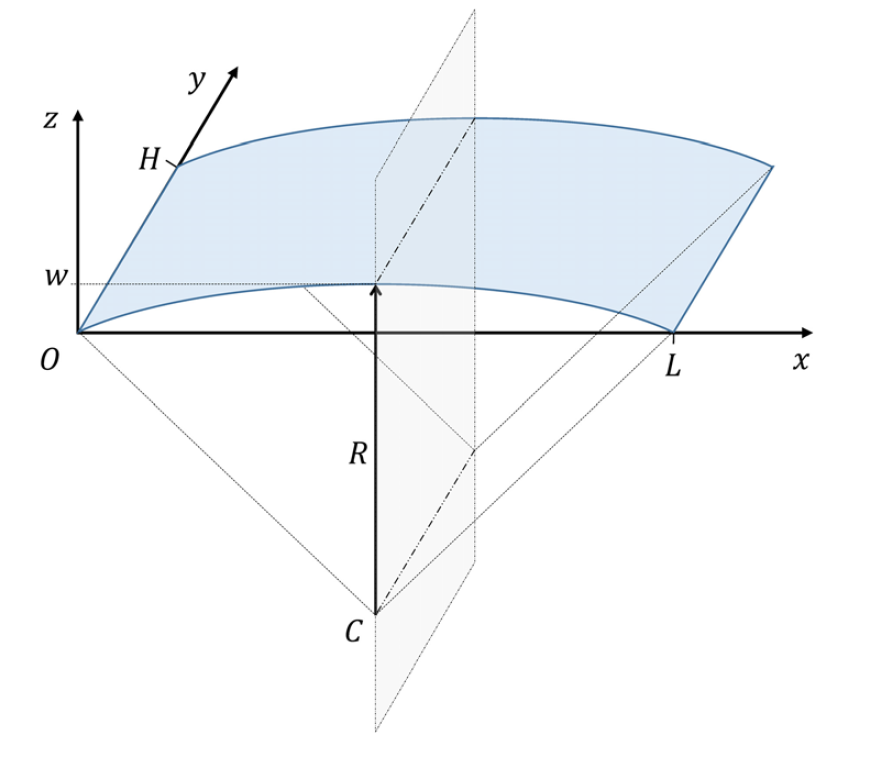

Here we take density $\rho$ and Young's modulus $E$ as system parameters and compute the sensitvity of SSM with respect to them. Here we take Rayleigh damping below


$$C=\alpha M+\beta K$$


the coefficients $\alpha$ and $\beta$ are choosen in the following two ways

- they are choosen such that the damping ratio of the first two modes are equal to 0.004 at nominal values of $\rho$ and $E$. In this case, both $\alpha$ and $\beta$ are constants;

- they are choosen such that the damping ratio of the first mode is fixed as a given value. In this case, $\alpha$ and $\beta$ can be $\omega$ dependent.

### Create dynamical model

clear all;
ngrids = 10;
E   = 70e9;
rho = 2700; Om = 148;
al = 0.402153037834110;
be = 8.631167461080214e-06;
[M,K,fnl,fext,DM,DK,dfnl2,dfnl3,dfext,outdof] = build_model_semi(ngrids,E,rho);

Building FE model
Loaded matrices and tensors from storage


DS = DynamicalSystem();
set(DS,'M',M,'C',al*M+be*K,'K',K,'fnl_semi',fnl);
set(DS.Options,'Emax',3,'Nmax',6)
set(DS,'DM',DM,'DK',DK);
set(DS,'al',@(x) al,'be',@(x) be,'dal',@(x) 0,'dbe',@(x) 0);
set(DS,'Dfnl2_semi',dfnl2,'Dfnl3_semi',dfnl3);
set(DS,'fext',fext,'Omega',Om,'dfext',dfext);
[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.269789e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4745i
  -0.0029 - 1.4745i
  -0.0063 + 3.1598i
  -0.0063 - 3.1598i
  -0.0094 + 4.1319i
  -0.0094 - 4.1319i



### SSM computation - explicit computation

S = SSM(DS);
set(S.Options,'solver','backslash');
resonant_modes = [1 2]; % choose master spectral subspace
S.choose_E(resonant_modes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     0     2
     3     0
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1598i
  -0.0063 - 3.1598i
  -0.0094 + 4.1319i
  -0.0094 - 4.1319i

sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0029 + 1.4745i
  -0.0029 - 1.4745i

sigma_in = 3


order = 3; % SSM expansion order
[We,Re] = S.explicit_whisker();


 second order explict solution 


### SSM computation - via SSMTool parameterization

Building FE model


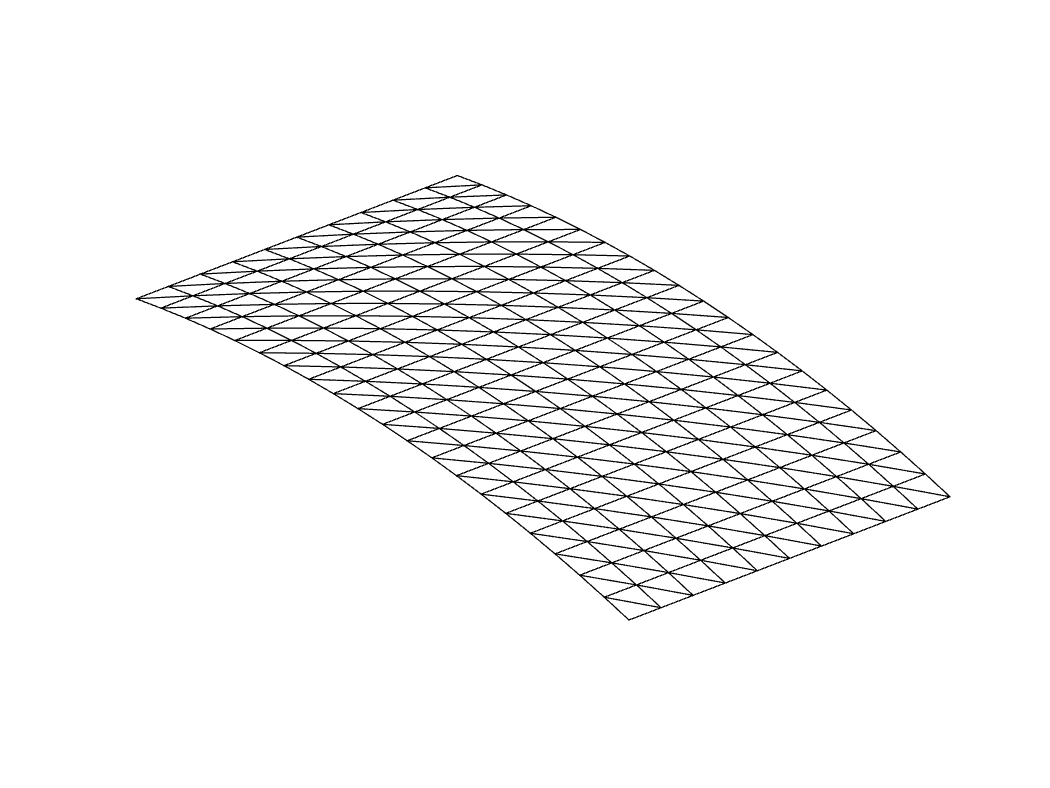

Getting nonlinearity coefficients
Loaded matrices and tensors from storage
Using Rayleigh damping
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.269789e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4745i
  -0.0029 - 1.4745i
  -0.0063 + 3.1598i
  -0.0063 - 3.1598i
  -0.0094 + 4.1319i
  -0.0094 - 4.1319i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.

[W_0,R_0,W_1,R_1] = ssmtool_comp(ngrids,E,rho,'type1',Om);

### SSM senstivity computation

[DW,DR] = S.explicit_senstivity_whisker(We,Re);


 damping ratio is 2.000000e-03


DW10 = DW.DW10; DW20 = DW.DW20; DW11 = DW.DW11;
DW30 = DW.DW30; DW21 = DW.DW21; Dx0 = DW.Dx0;
Dlamd = DR.Dlamd; Dr21 = DR.Dr21;
Dom = DR.Dom; Dpsi = DR.Dpsi; Dftilde = DR.Dftilde;

### Comparison of SSM results 

#### Explicit solution and SSMTool solution

fprintf('\n difference in terms of W10 \n')


 difference in terms of W10 


norm(We.W10-full(W_0(1).coeffs(:,2)))/norm(We.W10)

ans = 9.4898e-17

fprintf('\n difference in terms of W20 \n')


 difference in terms of W20 


norm(We.W20-full(W_0(2).coeffs(:,3)))/norm(We.W20)

ans = 1.5864e-13

fprintf('\n difference in terms of W11 \n')


 difference in terms of W11 


norm(We.W11-full(W_0(2).coeffs(:,2)))/norm(We.W11)

ans = 8.9399e-13

fprintf('\n difference in terms of W30 \n')


 difference in terms of W30 


norm(We.W30-full(W_0(3).coeffs(:,4)))/norm(We.W30)

ans = 1.7663e-12

fprintf('\n difference in terms of W21 \n')


 difference in terms of W21 


norm(We.W21-full(W_0(3).coeffs(:,3)))/norm(We.W21)

ans = 1.6430e-08

fprintf('\n difference in terms of x0 \n')


 difference in terms of x0 


norm(We.x0-W_1(2).W.coeffs)/norm(We.x0)

ans = 2.9343e-11

fprintf('\n difference in terms of gamma \n')


 difference in terms of gamma 


abs(Re.r21-full(R_0(3).coeffs(1,2)))/abs(Re.r21)

ans = 2.0519e-13

fprintf('\n difference in terms of ftilde \n')


 difference in terms of ftilde 


abs(Re.ftilde-R_1(2).R.coeffs(1))/abs(Re.ftilde)

ans = 2.7261e-14

Note: if solver='lsqminnorm', difference can be much more significant

### Compare results - sensitivity of SSM. (Explicit vs central finite difference)

#### Derivatives w.r.t $\rho$

% compute perturbed SSMs
drho = 0.001*rho;
ssm_rhop = comp_ssm(ngrids,E,rho+drho,Om,'type1');

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000364e-03
modal damping ratio for 2 mode is 1.999637e-03
modal damping ratio for 3 mode is 2.269141e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4738i
  -0.0029 - 1.4738i
  -0.0063 + 3.1582i
  -0.0063 - 3.1582i
  -0.0094 + 4.1298i
  -0.0094 - 4.1298i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1582i
  -0.0063 + 3.1582i
  -0.0063 - 3

ssm_rhom = comp_ssm(ngrids,E,rho-drho,Om,'type1');

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.999636e-03
modal damping ratio for 2 mode is 2.000364e-03
modal damping ratio for 3 mode is 2.270437e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4753i
  -0.0030 - 1.4753i
  -0.0063 + 3.1614i
  -0.0063 - 3.1614i
  -0.0094 + 4.1339i
  -0.0094 - 4.1339i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1614i
  -0.0063 + 3.1614i
  -0.0063 - 3

% Calculate derivatives
dw10_drho = (ssm_rhop.W10-ssm_rhom.W10)/(2*drho);
dw20_drho = (ssm_rhop.W20-ssm_rhom.W20)/(2*drho);
dw11_drho = (ssm_rhop.W11-ssm_rhom.W11)/(2*drho);
dw30_drho = (ssm_rhop.W30-ssm_rhom.W30)/(2*drho);
dw21_drho = (ssm_rhop.W21-ssm_rhom.W21)/(2*drho);
dpsi_drho = (ssm_rhop.psi-ssm_rhom.psi)/(2*drho);
dlam_drho = (ssm_rhop.lamd-ssm_rhom.lamd)/(2*drho);
dr21_drho = (ssm_rhop.r21-ssm_rhom.r21)/(2*drho);
dx0_drho  = (ssm_rhop.x0-ssm_rhom.x0)/(2*drho);
dftilde_drho = (ssm_rhop.ftilde-ssm_rhom.ftilde)/(2*drho);

% compute relative or absolute errors and print them 
fprintf('relative error for dw10_drho is %d\n', norm(DW10(:,1)-dw10_drho)/norm(DW10(:,1))); 

relative error for dw10_drho is 9.999192e-07


fprintf('relative error for dw20_drho is %d\n', norm(DW20(:,1)-dw20_drho)/norm(DW20(:,1))); 

relative error for dw20_drho is 1.457963e-06


fprintf('relative error for dw11_drho is %d\n', norm(DW11(:,1)-dw11_drho)/norm(DW11(:,1))); 

relative error for dw11_drho is 1.204816e-06


fprintf('relative error for dw30_drho is %d\n', norm(DW30(:,1)-dw30_drho)/norm(DW30(:,1))); 

relative error for dw30_drho is 2.000639e-06


fprintf('relative error for dw21_drho is %d\n', norm(DW21(:,1)-dw21_drho)/norm(DW21(:,1))); 

relative error for dw21_drho is 7.477640e-06


fprintf('relative error for dpsi_drho is %d\n', norm(Dpsi(:,1)-dpsi_drho)/norm(Dpsi(:,1))); 

relative error for dpsi_drho is 3.051626e-05


fprintf('relative error for dlamd_drho is %d\n', norm(Dlamd(1)-dlam_drho)/norm(Dlamd(1))); 

relative error for dlamd_drho is 6.248437e-07


fprintf('relative error for dr21_drho is %d\n', norm(Dr21(1)-dr21_drho)/norm(Dr21(1)));

relative error for dr21_drho is 1.459034e-06


fprintf('absolute error for dx0_drho is %d\n', norm(Dx0(:,1)-dx0_drho)/norm(Dx0(:,1)));

absolute error for dx0_drho is 7.749303e-07


fprintf('absolute error for dftilde_drho is %d\n', abs(Dftilde(1)-dftilde_drho)/abs(dftilde_drho));

absolute error for dftilde_drho is 3.097446e-05


#### Derivatives w.r.t $E$

% computation of peturbed SSMs
dE = 0.001*E; 
ssm_Ep = comp_ssm(ngrids,E+dE,rho,Om,'type1');

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.999637e-03
modal damping ratio for 2 mode is 2.000364e-03
modal damping ratio for 3 mode is 2.270437e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4753i
  -0.0030 - 1.4753i
  -0.0063 + 3.1614i
  -0.0063 - 3.1614i
  -0.0094 + 4.1339i
  -0.0094 - 4.1339i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1614i
  -0.0063 + 3.1614i
  -0.0063 - 3

ssm_Em = comp_ssm(ngrids,E-dE,rho,Om,'type1');

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000364e-03
modal damping ratio for 2 mode is 1.999636e-03
modal damping ratio for 3 mode is 2.269140e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4738i
  -0.0029 - 1.4738i
  -0.0063 + 3.1582i
  -0.0063 - 3.1582i
  -0.0094 + 4.1298i
  -0.0094 - 4.1298i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1582i
  -0.0063 + 3.1582i
  -0.0063 - 3

% calculate derivatives
dw10_dE = (ssm_Ep.W10-ssm_Em.W10)/(2*dE);
dw20_dE = (ssm_Ep.W20-ssm_Em.W20)/(2*dE);
dw11_dE = (ssm_Ep.W11-ssm_Em.W11)/(2*dE);
dw30_dE = (ssm_Ep.W30-ssm_Em.W30)/(2*dE);
dw21_dE = (ssm_Ep.W21-ssm_Em.W21)/(2*dE);
dlam_dE = (ssm_Ep.lamd-ssm_Em.lamd)/(2*dE);
dr21_dE = (ssm_Ep.r21-ssm_Em.r21)/(2*dE);
dx0_dE  = (ssm_Ep.x0-ssm_Em.x0)/(2*dE);
dftilde_dE = (ssm_Ep.ftilde-ssm_Em.ftilde)/(2*dE);

% compute relative or absolute errors and print them
fprintf('absolute error for dw10_dE is %d\n', norm(DW10(:,2)-dw10_dE)); 

absolute error for dw10_dE is 9.066964e-16


fprintf('absolute error for dw20_dE is %d\n', norm(DW20(:,2)-dw20_dE)); 

absolute error for dw20_dE is 3.352973e-07


fprintf('absolute error for dw11_dE is %d\n', norm(DW11(:,2)-dw11_dE)); 

absolute error for dw11_dE is 4.752090e-10


fprintf('absolute error for dw30_dE is %d\n', norm(DW30(:,2)-dw30_dE)); 

absolute error for dw30_dE is 2.296694e-06


fprintf('absolute error for dw21_dE is %d\n', norm(DW21(:,2)-dw21_dE)); 

absolute error for dw21_dE is 1.412176e-06


fprintf('absolute error for dlamd_dE is %d\n', norm(Dlamd(2)-dlam_dE)); 

absolute error for dlamd_dE is 1.318809e-16


fprintf('absolute error for dr21_dE is %d\n', norm(Dr21(2)-dr21_dE));

absolute error for dr21_dE is 4.062666e-07


fprintf('absolute error for dx0_dE is %d\n', norm(Dx0(:,2)-dx0_dE));

absolute error for dx0_dE is 2.126286e-18


fprintf('absolute error for dftilde_dE is %d\n', norm(Dftilde(2)-dftilde_dE));

absolute error for dftilde_dE is 1.409253e-19


#### Curvature of SSM

% calculate curvature
Curv = We.W20'*We.W20+We.W11'*We.W11

Curv =    (1,1)        5.508802932530965e+08


% derivatives of curvature
DCurv = 2*real(We.W20'*DW.DW20)+2*(We.W11'*DW.DW11)

DCurv = 1.0e+05 *

  -6.120862183065789   0.000000236090398


### Perturbed SSMs

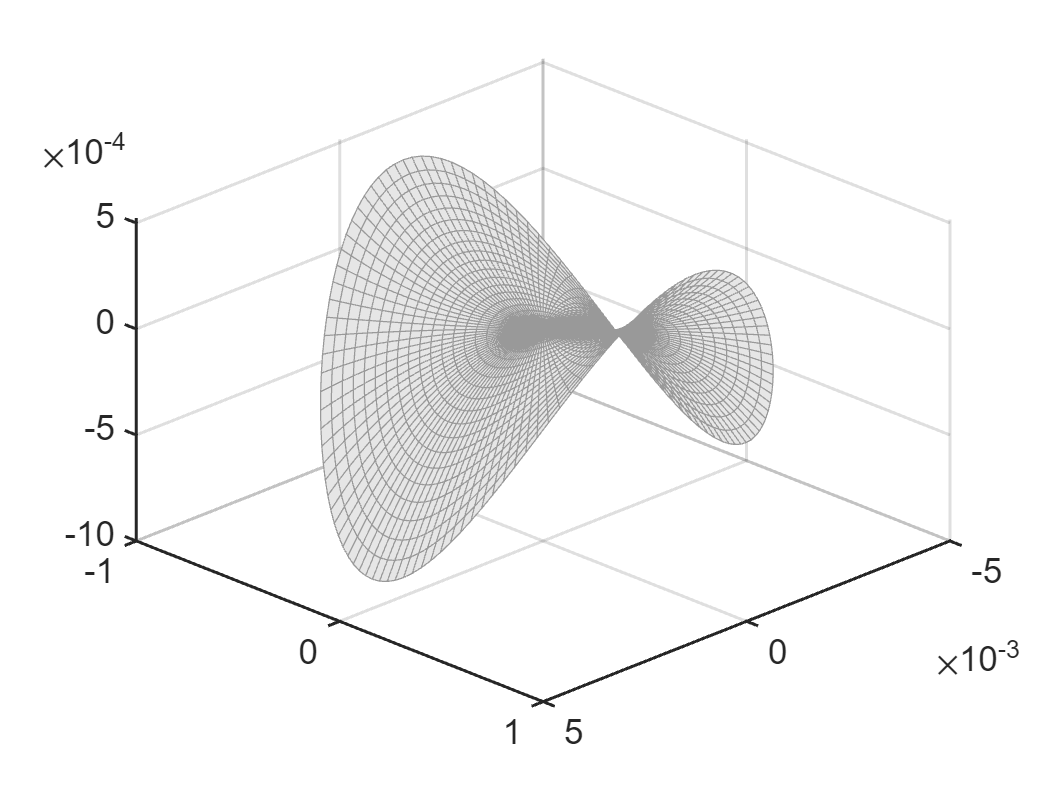

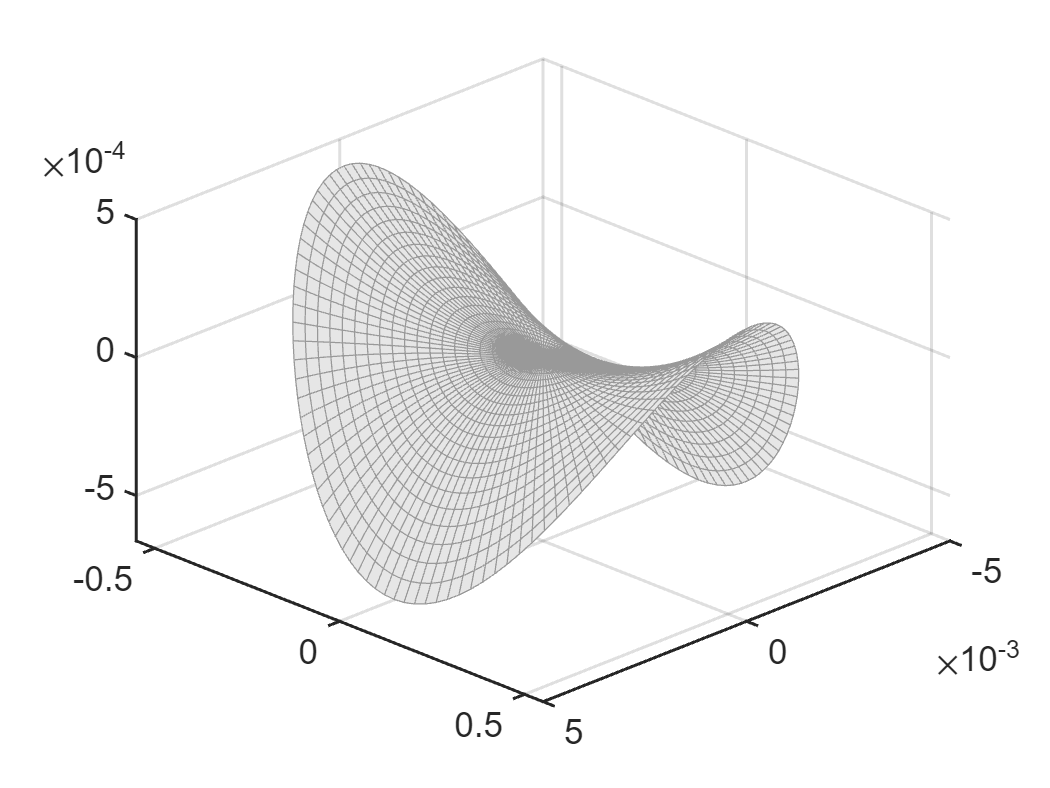

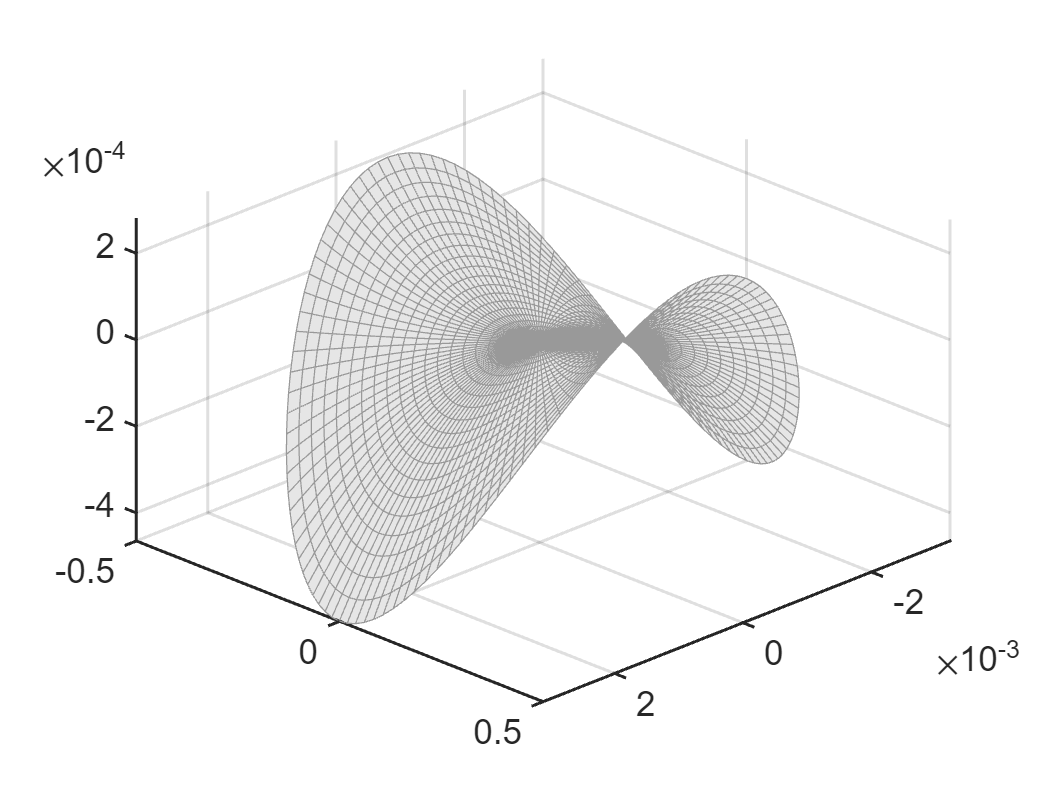

% [l/2,3b/4]: 330
% [l/2,2b/4]: 660
% [l/2,1b/4]: 990 - outdof
rhosamp = linspace(0,0.01,21); plotdof = [outdof outdof+size(M,1) 660];
zmesh = S.SSM_sensitivity(We,DW,rhosamp,plotdof,1,[-0.3 0 0.3]*rho);

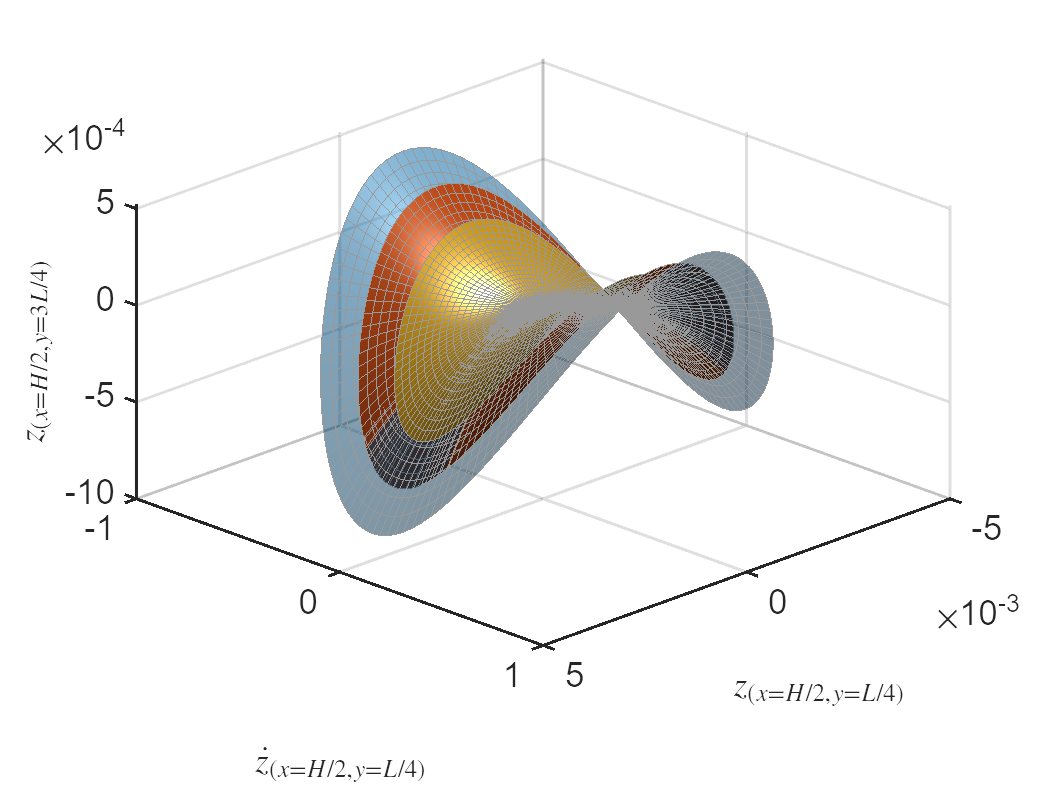

colors = get(0,'defaultaxescolororder');
% 0.6*[1 1 1]
figure; hold on
h = surf(zmesh{1}.zdof1,zmesh{1}.zdof2,zmesh{1}.zdof3,'FaceColor', colors(1,:), 'FaceAlpha', 0.5, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
view([1,1,1])
grid on
set(gca,'LineWidth',1.2);
set(gca,'FontSize',14);

surf(zmesh{2}.zdof1,zmesh{2}.zdof2,zmesh{2}.zdof3,'FaceColor', colors(2,:), 'FaceAlpha', 1, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
surf(zmesh{3}.zdof1,zmesh{3}.zdof2,zmesh{3}.zdof3,'FaceColor', colors(3,:), 'FaceAlpha', 1, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
camlight; lighting gouraud
xlabel('$z_{(x=H/2,y=L/4)}$','FontSize',14,'Interpreter','latex');
ylabel('$\dot{z}_{(x=H/2,y=L/4)}$','FontSize',14,'Interpreter','latex');
zlabel('${z}_{(x=H/2,y=3L/4)}$','FontSize',14,'Interpreter','latex');

### Perturbed backbone curves

freqRange = [138 155];
pidx   = 1; pfracs = [-0.02 0 0.02]*rho;
pBBs = S.BB_sensitivity(We,Re,DW,DR,outdof,freqRange,pidx,pfracs);

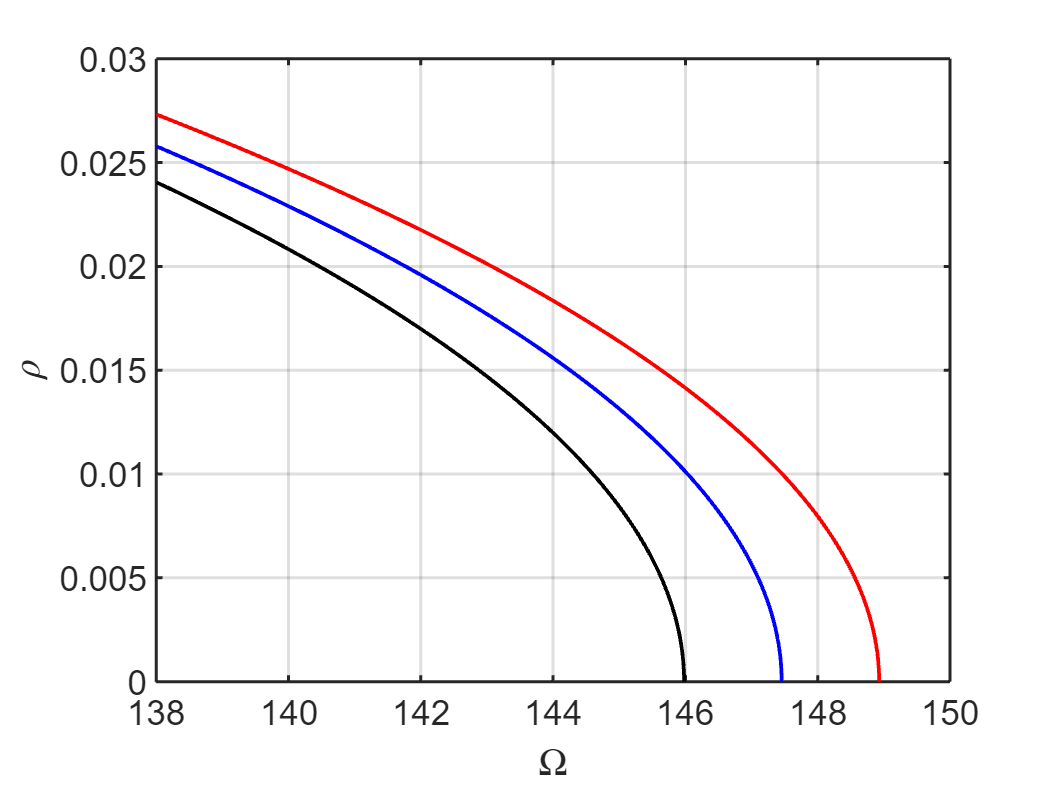

figure; hold on
plot(pBBs{1}.om,pBBs{1}.rho,'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.rho,'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.rho,'k-','LineWidth',1.5)
grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$\rho$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

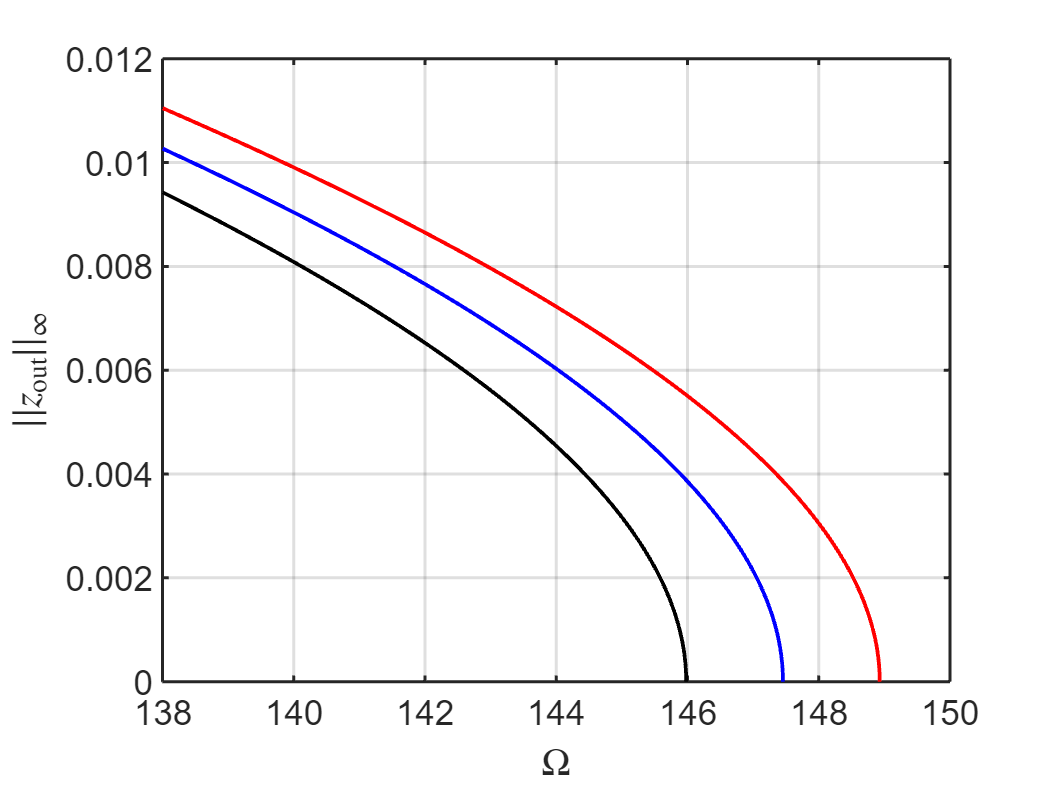

figrho = gcf;

figure; hold on
plot(pBBs{1}.om,pBBs{1}.ampLinf(1,:),'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.ampLinf(1,:),'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.ampLinf(1,:),'k-','LineWidth',1.5)
grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$||z_\mathrm{out}||_\infty$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

figz1 = gcf;

Direct computation - for the purpose of validation

bbp1 = comp_bb(ngrids,E,rho+pfracs(1),freqRange);

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.992755e-03
modal damping ratio for 2 mode is 2.007449e-03
modal damping ratio for 3 mode is 2.283001e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4895i
  -0.0030 - 1.4895i
  -0.0064 + 3.1919i
  -0.0064 - 3.1919i
  -0.0095 + 4.1738i
  -0.0095 - 4.1738i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0064 + 3.1919i
  -0.0064 + 3.1919i
  -0.0064 - 3

bbp3 = comp_bb(ngrids,E,rho+pfracs(3),freqRange);

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.007299e-03
modal damping ratio for 2 mode is 1.992897e-03
modal damping ratio for 3 mode is 2.257063e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4600i
  -0.0029 - 1.4600i
  -0.0062 + 3.1287i
  -0.0062 - 3.1287i
  -0.0092 + 4.0911i
  -0.0092 - 4.0911i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0062 + 3.1287i
  -0.0062 + 3.1287i
  -0.0062 - 3

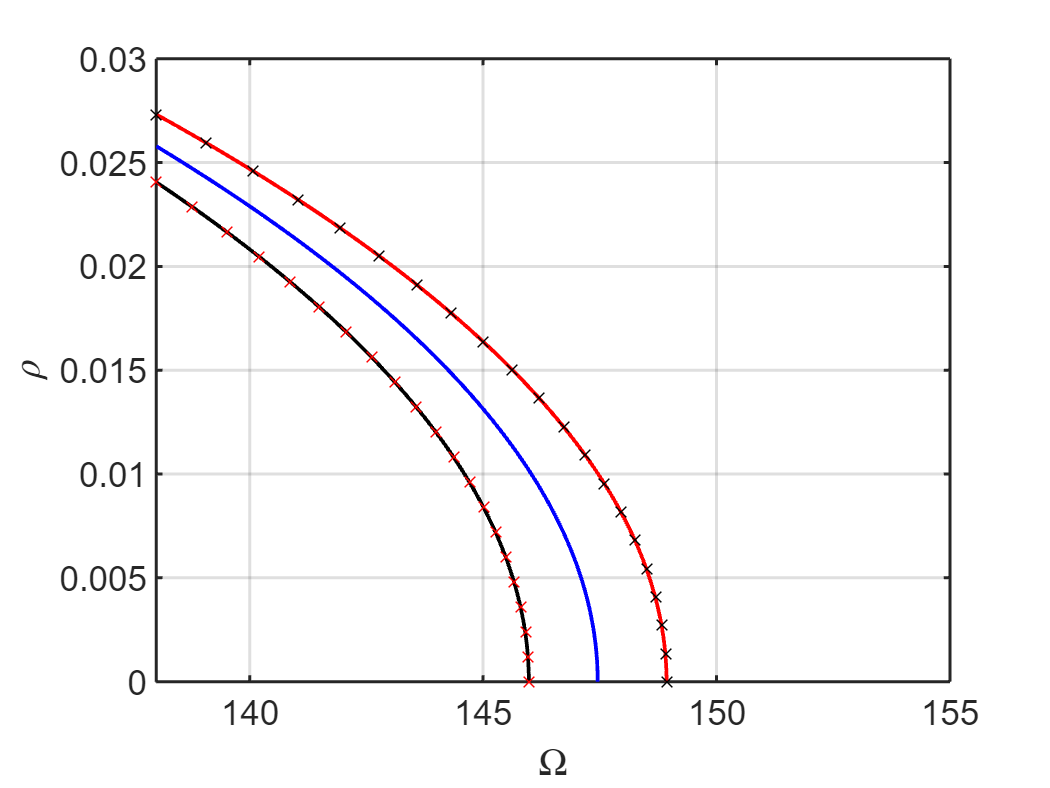

figure(figrho); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.rho(1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.rho(1:5:end),'rx')
xlim(freqRange)

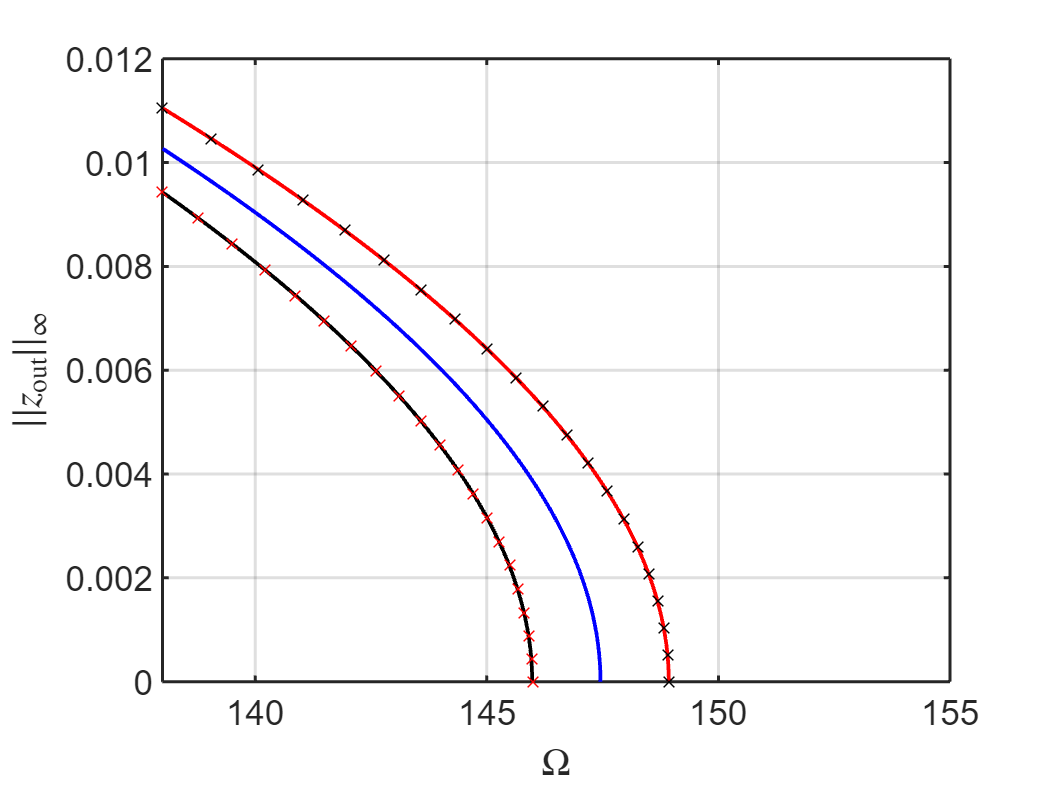

figure(figz1); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.ampLinf(1,1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.ampLinf(1,1:5:end),'rx')
xlim(freqRange)

## Forced vibration

### Sensitivity of forced periodic response

optdof = outdof; Q = 1; epsilon = 0.1;
[frce,dfrce] = S.po_sensitivity(We,Re,DW,DR,optdof,Q,epsilon);

### Validation via central finite difference

- with respect to $\rho$

drho = rho*0.001;
frc_mp = comp_frc(ngrids,E,rho+drho,Om,Q,epsilon,freqRange);

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000364e-03
modal damping ratio for 2 mode is 1.999637e-03
modal damping ratio for 3 mode is 2.269141e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4738i
  -0.0029 - 1.4738i
  -0.0063 + 3.1582i
  -0.0063 - 3.1582i
  -0.0094 + 4.1298i
  -0.0094 - 4.1298i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1582i
  -0.0063 + 3.1582i
  -0.0063 - 3

frc_mm = comp_frc(ngrids,E,rho-drho,Om,Q,epsilon,freqRange);

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.999636e-03
modal damping ratio for 2 mode is 2.000364e-03
modal damping ratio for 3 mode is 2.270437e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4753i
  -0.0030 - 1.4753i
  -0.0063 + 3.1614i
  -0.0063 - 3.1614i
  -0.0094 + 4.1339i
  -0.0094 - 4.1339i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0063 + 3.1614i
  -0.0063 + 3.1614i
  -0.0063 - 3

drho_drho = (frc_mp.rho - frc_mm.rho)/(2*drho);
dth_drho  = (frc_mp.th - frc_mm.th)/(2*drho);
damp_drho = (frc_mp.amp - frc_mm.amp)/(2*drho);
drhomax_drho = (frc_mp.rhomax-frc_mm.rhomax)/(2*drho);
dommax_drho  = (frc_mp.Ommax-frc_mm.Ommax)/(2*drho);
% calculate derivatives
fprintf('relative error for drho_drho is %d\n', abs((dfrce.Drho(1)-drho_drho)/dfrce.Drho(1))); 

relative error for drho_drho is 7.224863e-04


fprintf('relative error for dth_drho is %d\n', abs((dfrce.Dth(1)-dth_drho)/dfrce.Dth(1))); 

relative error for dth_drho is 1.181298e-04


fprintf('relative error for damp_drho is %d\n', abs((dfrce.Damp(1)-damp_drho)/dfrce.Damp(1)));

relative error for damp_drho is 6.919985e-04


fprintf('absolute error for drhomax_drho is %d\n', abs((dfrce.Drhomax(1)-drhomax_drho)/dfrce.Drhomax(1)));

absolute error for drhomax_drho is 2.811953e-07


fprintf('absolute error for dommax_drho is %d\n', abs((dfrce.DOmmax(1)-dommax_drho)/dfrce.DOmmax(1)));

absolute error for dommax_drho is 6.299883e-07


### Peturbed FRCs

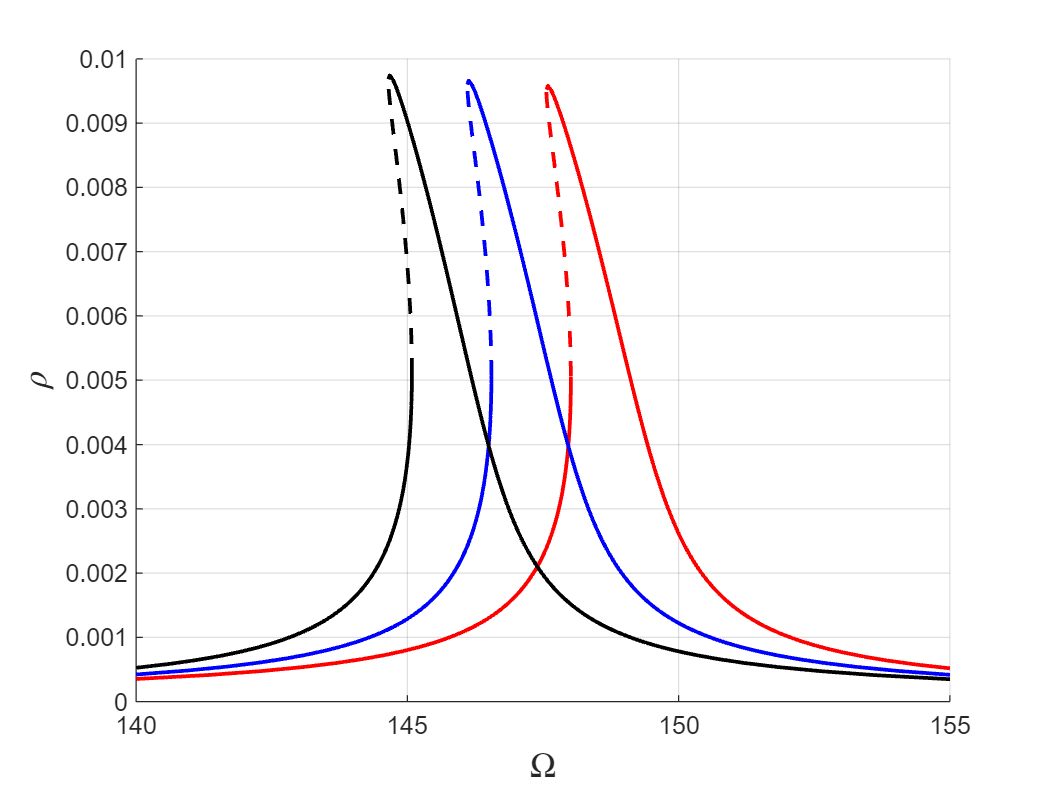

% perturbed FRC
set(S.Options,'contribNonAuto',false)
freqRange = [140 155];
pidx = 1; pfracs = [-0.02 0 0.02]*rho;
pFRCs = S.FRC_sensitivity(We,Re,DW,DR,optdof,Q,epsilon,freqRange,pidx,pfracs);

ST1 = cell(2,1);
ST1{1} = {'r--','LineWidth',1.5}; % unstable
ST1{2} = {'r-','LineWidth',1.5};  % stable
ST2 = cell(2,1);
ST2{1} = {'b--','LineWidth',1.5}; % unstable
ST2{2} = {'b-','LineWidth',1.5};  % stable
ST3 = cell(2,1);
ST3{1} = {'k--','LineWidth',1.5}; % unstable
ST3{2} = {'k-','LineWidth',1.5};  % stable

figure; hold on
plot_stab_lines(pFRCs{1}.om,pFRCs{1}.rho,pFRCs{1}.st,ST1);
plot_stab_lines(pFRCs{2}.om,pFRCs{2}.rho,pFRCs{2}.st,ST2);
plot_stab_lines(pFRCs{3}.om,pFRCs{3}.rho,pFRCs{3}.st,ST3);
xlim(freqRange); grid on; 
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$\rho$','FontSize',14,'Interpreter','latex');

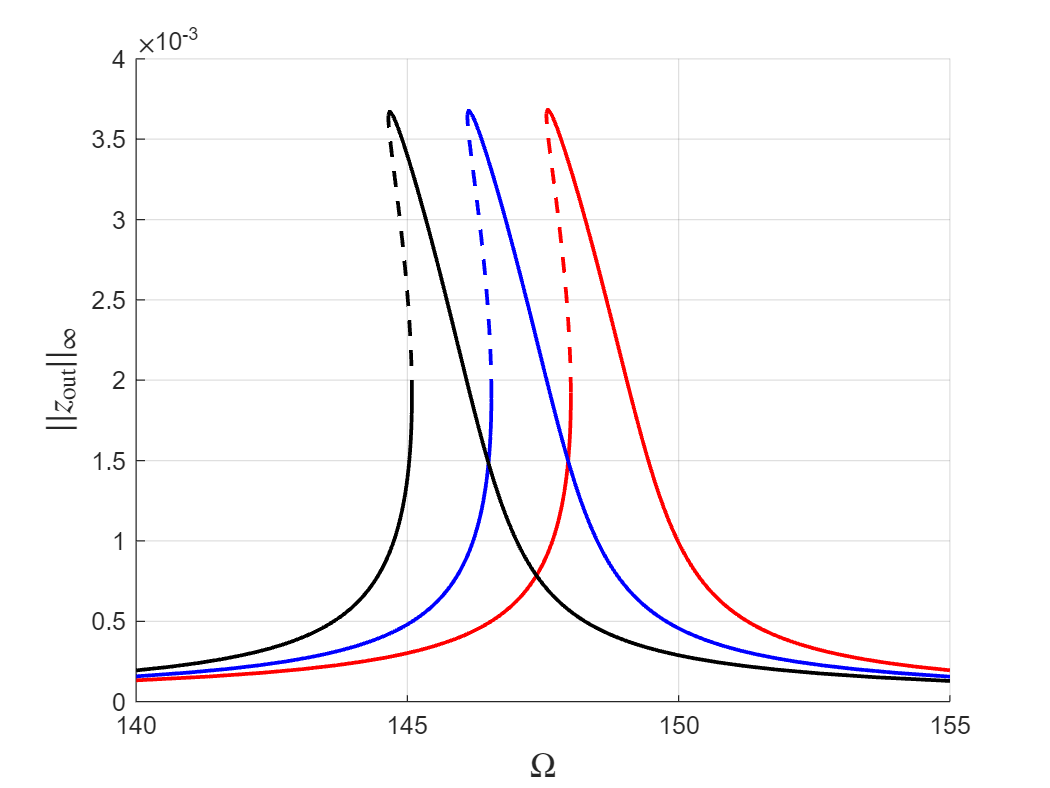

figrho = gcf;
figure; hold on
plot_stab_lines(pFRCs{1}.om,pFRCs{1}.ampLinf,pFRCs{1}.st,ST1);
plot_stab_lines(pFRCs{2}.om,pFRCs{2}.ampLinf,pFRCs{2}.st,ST2);
plot_stab_lines(pFRCs{3}.om,pFRCs{3}.ampLinf,pFRCs{3}.st,ST3);
xlim(freqRange); grid on; 
xlabel('$\Omega$','FontSize',14,'Interpreter','latex')
ylabel('$||z_\mathrm{out}||_\infty$','FontSize',14,'Interpreter','latex')

figamp = gcf;

Direct computation - for the purpose of validation

[~,frcp1] = comp_frc(ngrids,E,rho+pfracs(1),Om,Q,epsilon,freqRange);

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.992755e-03
modal damping ratio for 2 mode is 2.007449e-03
modal damping ratio for 3 mode is 2.283001e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4895i
  -0.0030 - 1.4895i
  -0.0064 + 3.1919i
  -0.0064 - 3.1919i
  -0.0095 + 4.1738i
  -0.0095 - 4.1738i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0064 + 3.1919i
  -0.0064 + 3.1919i
  -0.0064 - 3

[~,frcp3] = comp_frc(ngrids,E,rho+pfracs(3),Om,Q,epsilon,freqRange)

Building FE model
Loaded matrices and tensors from storage
Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.007299e-03
modal damping ratio for 2 mode is 1.992897e-03
modal damping ratio for 3 mode is 2.257063e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0029 + 1.4600i
  -0.0029 - 1.4600i
  -0.0062 + 3.1287i
  -0.0062 - 3.1287i
  -0.0092 + 4.0911i
  -0.0092 - 4.0911i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0062 + 3.1287i
  -0.0062 + 3.1287i
  -0.0062 - 3

frcp3 = 1×1 cell array
    {1×1 struct}


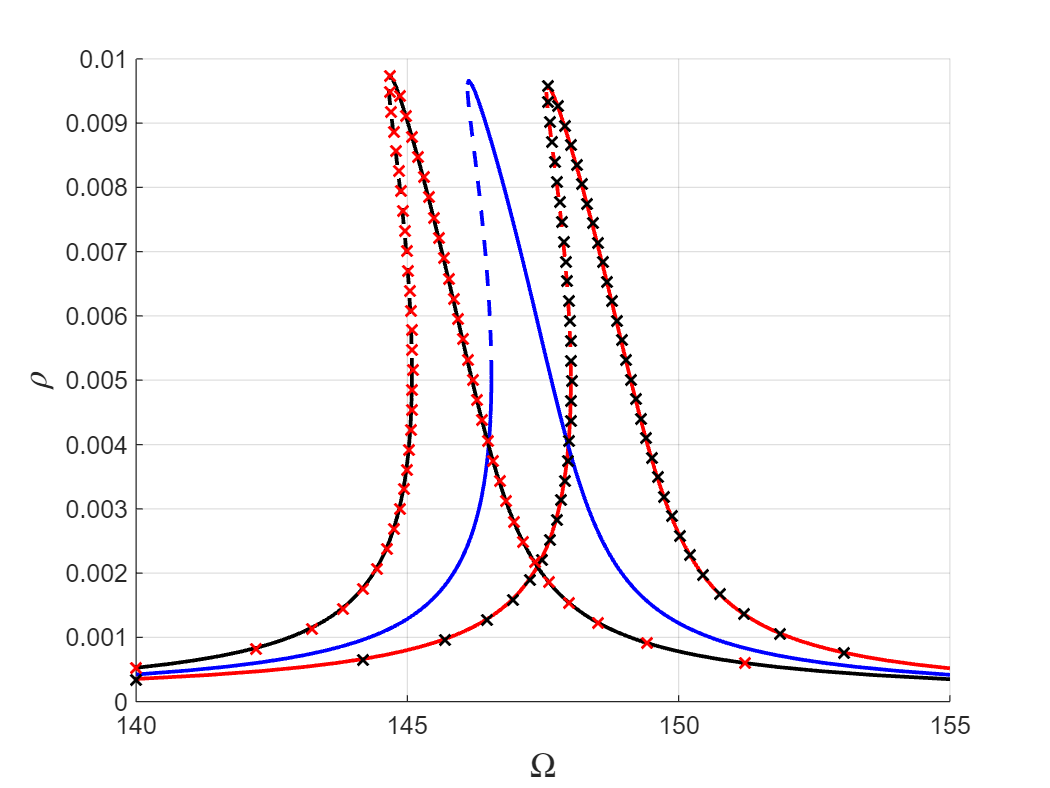

figure(figrho); hold on
idx1 = [1,5,10:10:numel(frcp1{1}.om),numel(frcp1{1}.om)-5,numel(frcp1{1}.om)];
idx3 = [1,5,10:10:numel(frcp3{1}.om),numel(frcp3{1}.om)-5,numel(frcp3{1}.om)];
plot(frcp1{1}.om(1:5:end),frcp1{1}.rho(1:5:end),'kx','LineWidth',1)
plot(frcp3{1}.om(1:5:end),frcp3{1}.rho(1:5:end),'rx','LineWidth',1)

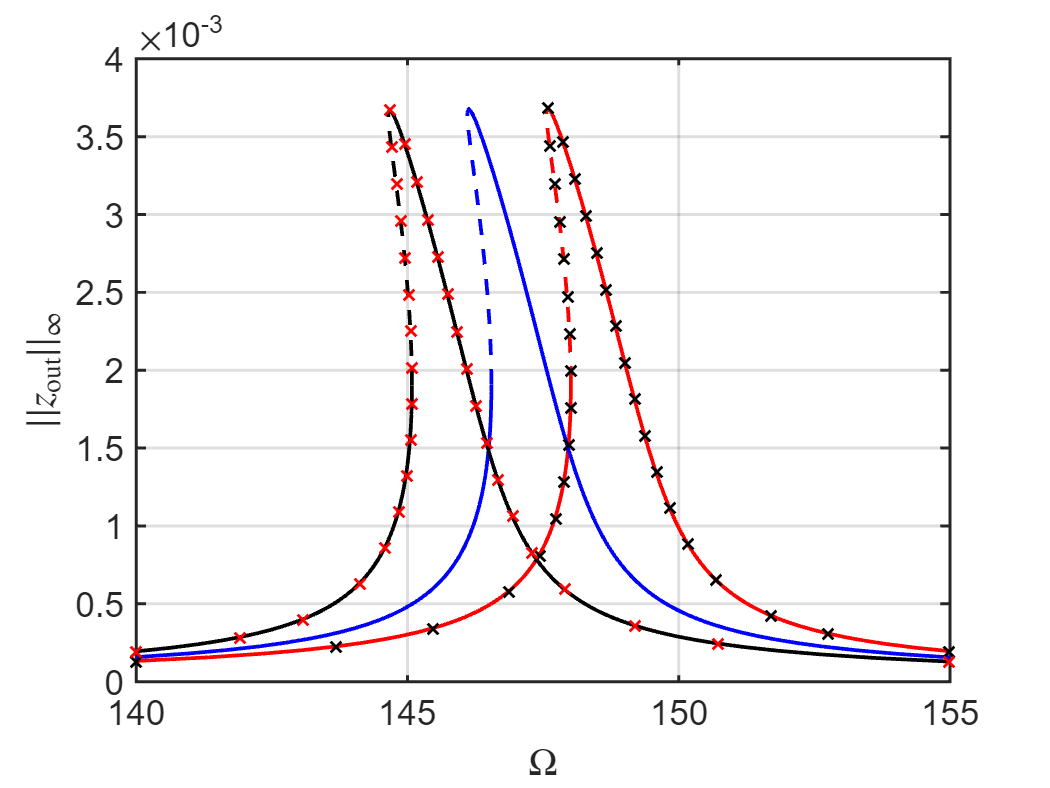

figure(figamp); hold on
plot(frcp1{1}.om(idx1),frcp1{1}.ampLinf(idx1),'kx','LineWidth',1)
plot(frcp3{1}.om(idx3),frcp3{1}.ampLinf(idx3),'rx','LineWidth',1)
grid on; box on
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);